# **PS922 Issues in Psychological Science**

# Modelling Assignment

# Student ID: 1860529

## Part 1

clear all

### **Question 1: Plot a graph illustrating the different predictions of Fechner's law and Steven's law.** 

Based on the structure of Steven's law, I have two different cases (one with the alpha larger than 1, one with alpha smaller than 1) for comparison. Besides, the stimulus energies are ranging between 1 and 100. 

clf
f = figure;
p = uipanel('Parent', f, 'BorderType', 'none');
p.Title = 'Fechners Law vs. Stevens Law';
p.TitlePosition = 'centertop';
p.FontSize = 14;
p.FontWeight = 'bold';

subplot(2, 1, 1, 'Parent', p);
for k = 1:1:3
    i = 1:100; a = 0.35;
    FS = k.*log(i); SS = k.*(i.^a);
    hold on
    plot(i, FS, '-.', 'Color', [40,71,92]/255, 'LineWidth', 3);
    plot(i, SS, 'Color', [139,166,147]/255, 'LineWidth', 3);
    % Point out different value of the parameter k:
    text(40, 3.673, '\leftarrow k = 1', 'fontsize', 12);
    text(40, 7.274, '\leftarrow k = 2', 'fontsize', 12);
    text(40, 10.91, '\leftarrow k = 3', 'fontsize', 12);
    legend('Fechners Law', 'Stevens Law', 'fontsize', 12);
    xlabel('Stimulus Intensity', 'fontsize', 14);
    ylabel('Subjective Magnitude', 'fontsize', 14);
    title('a < 1', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold off
end

subplot(2, 1, 2, 'Parent', p);
for k = 1:1:3
    i = 1:100; a = 1.35;
    FS = k*log(i); SS = k*(i.^a);
    hold on
    plot(i, FS, '-.', 'Color', [40,71,92]/255, 'LineWidth', 3);
    plot(i, SS, 'Color', [139,166,147]/255, 'LineWidth', 3);
    text(40, 145.5, '\leftarrow k = 1', 'fontsize', 12);
    text(40, 290.9, '\leftarrow k = 2', 'fontsize', 12);
    text(40, 436.4, '\leftarrow k = 3', 'fontsize', 12);
    legend('Fechners Law', 'Stevens Law', 'fontsize', 12);
    xlabel('Stimulus Intensity', 'fontsize', 14);
    ylabel('Subjective Magnitude', 'fontsize', 14);
    title('a > 1', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold off
end

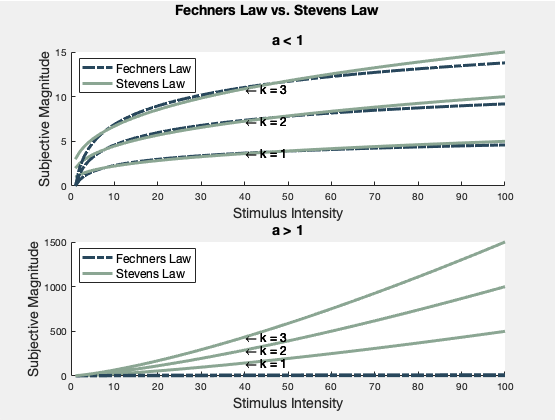

With the increase of k, both curves of Fechner's law and Steven's law have moved upward. However, compared to the case when alpha in Steven's law is smaller than 1, the function for Steven's law is increasing in a much larger speed (the value of subjective magnitude is much larger in the function of Steven's law compared to the one in Fechner's law) when alpha is larger than 1. 

### **Question 2: Plot a graph illustrating the effects of varying the alpha parameter in Steven's law.** 

Here I separate the situations into two cases as in question one. Two different cases will give us two different results of the relationship between physical stimulus and subjective magnitude regarding Steven's law. 

clf
f = figure;
p = uipanel('Parent', f, 'BorderType', 'none');
p.Title = 'Effects of varying alpha in Stevens Law';
p.TitlePosition = 'centertop';
p.FontSize = 14;
p.FontWeight = 'bold';
% Give a different color for each curve:
c = [[0,6,35]/255; [40,71,92]/255; [74,108,116]/255; [139,166,147]/255; ...
    [240,227,192]/255];

subplot(2, 1, 1, 'Parent', p);
for j = 1:5
    a = 0.1:0.2:0.9; i = 1:100; k = 1;
    % Can also use a = linspace(0,1) for all the
    % possible values of a between 0 and 1.
    SS = k*(i.^a(j));
    plot(SS, ':', 'Color', c(j,:), 'LineWidth', 3);
    legend('a = 0.1', 'a = 0.3', 'a = 0.5', 'a = 0.7',...
        'a = 0.9', 'fontsize', 12);
    xlabel('Stimulus Intensity', 'fontsize', 14);
    ylabel('Subjective Magnitude', 'fontsize', 14);
    title('a < 1', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold on
end
hold off

subplot(2, 1, 2, 'Parent', p);
for j = 1:5
    a = 1:0.2:1.9; i = 1:100; k = 1;
    % Can also use a = linspace(1,2) for all the
    % possible values of a between 1 and 2.
    SS = k*(i.^a(j));
    plot(SS, ':', 'Color', c(j,:), 'LineWidth', 3);
    legend('a = 1.0', 'a = 1.3', 'a = 1.5', 'a = 1.7', ...
        'a = 1.9', 'fontsize', 12);
    xlabel('Stimulus Intensity', 'fontsize', 14);
    ylabel('Subjective Magnitude', 'fontsize', 14);
    title('a > 1', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold on
end
hold off

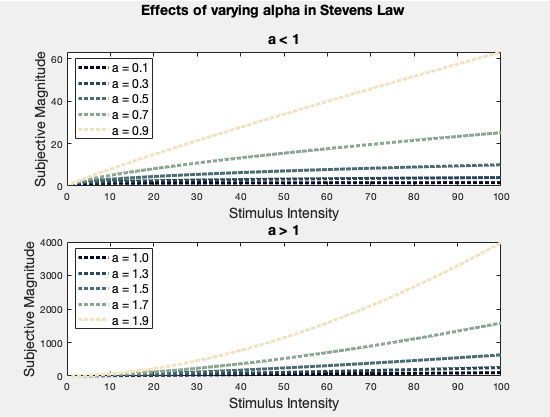

In Steven's law, when alpha increases, the subjective magnitude also increases. Specifically, when alpha is larger than 1, the value of subjective magnitude is much larger than the case when alpha is smaller than 1 (approximately about 70 times larger than the one with alpha smaller than 1). 

### **Question 3: Calculate the RMSD between Steven's law and data for various parameter values.** 

First check the effect of varying k on RMSD.

for k = 1:1:5
    a = 0.3; i = 2:2:12;
    data = [1.1 1.5 2.1 2.5 2.9 3.2];
    SS = k.*(i.^a);
    sd = (SS - data).^2;
    name_string = ['rmsd_with_k' num2str(k) '=sqrt(mean(sd))'];
    eval(name_string)
end

rmsd_with_k1 = 0.6560

rmsd_with_k2 = 1.2708

rmsd_with_k3 = 3.0026

rmsd_with_k4 = 4.7573

rmsd_with_k5 = 6.5165

The effect of varying alpha on RMSD.

a = 0.1; k = 1;
for m = 1:5
    i = 2:2:12;
    data = [1.1 1.5 2.1 2.5 2.9 3.2];
    SS = k.*(i.^a);
    sd = (SS - data).^2;
    name_string = ['rmsd_with_a' num2str(m) '=sqrt(mean(sd))'];
    eval(name_string)
    a = a + 0.2;
end

rmsd_with_a1 = 1.2195

rmsd_with_a2 = 0.6560

rmsd_with_a3 = 0.3458

rmsd_with_a4 = 1.7040

rmsd_with_a5 = 3.9238

We can also see the effect of varying both k and alpha by using the following command. 

% for a = 0.1:0.2:0.9
%     for k = 1:1:5
%         i = 2:2:12;
%         data = [1.1 1.5 2.1 2.5 2.9 3.2];
%         SS = k.*(i.^a);
%         sd = (SS - data).^2;
%         rmsd=sqrt(mean(sd))
%     end
% end

As we can see from the results, the smaller the values of k is, the smaller the values of the standard deviation and RMSD can be. When alpha is around 0.5, the standard deviation and RMSD are much smaller compared to other cases I checked. 

### **Question 4: Find by hand approximate parameter values that minimise RMSD.**

Based on the results from the previous question, I started with alpha = 0.5 and k = 1, in this way we can simplify the process to find the values of alpha and k to minimise RMSD by hand.

a = 0.65; k = 0.65; i = 2:2:12;
data = [1.1 1.5 2.1 2.5 2.9 3.2];
SS = k*(i.^a);
sd = (SS - data).^2;
rmsd = sqrt(mean(sd))

rmsd = 0.0601

I find out that when alpha = 0.65, k = 0.65, RMSD seems to have a minimum value of 0.0601. However, we can not possibly find the minimum value of RMSD by hand. Therefore, after creating a function called 'calcu' to calculate the RMSD (shows in the appendix), I find the minimum value of RMSD is 0.0539 (when alpha = 0.6341, k = 0.6661).

### **Question 5: Commentary noting any issues arising.**

Fechner’s Law ($S=k\cdot \log \left(l\right)$) and Steven’s Law ($S=k\cdot l^a$) measure the relationship between physical stimulus and subjective magnitude. Fechner’s Law and Steven’s Law both state that subjective magnitude increases with the increase of physical stimulations (positive relationship). Moreover, by using different values of the parameter k in the for-loops, one can see that with the increase of the parameter k, the effect of the physical stimulus on subjective magnitude increases.  

Fechner’s Law believes that the change in physical stimulations has a proportional logarithmic impact on subjective magnitude. This means that when the physical stimulation continues to increase its "power", the subjective magnitude will also increase. However, along with the increase of physical stimulation, the amount of value increased in people’s subjective magnitude will decrease (decreasing marginal effect). We can observe this phenomenon from the graph in question one. We can also find examples in real life situations to support this theory. For instance, if someone helps you with cleaning your house every week, for the first several weeks you might think that this is a very nice gesture, and you will appreciate it, but after a year, this helping behaviour will just become "too normal" for you, so the nice feeling you have has drastically decreased. 

However, Steven’s Law gives a more comprehensive explanation of the relationship between physical stimulus and subjective magnitude. One can see that the in the graph from question two, when the power exponent alpha is less than 1, the curve of Steven’s Law is similar to the one of Fechner’s Law. When the power exponent alpha is greater than 1, the increase in subjective magnitude is much more substantial compared to the cases when alpha is less than 1. In other words, Steven’s Law extended Fechner’s Law. It shows that when the level of stimulation is high (for instance, if you stay in a dangerous environment), people’s reaction will be different compared to the “normal” stimulation (follow the example, normal stimulation can be a safe environment you stay in on a daily basis). 

Steven’s Law has practical psychological significances. That is, people’s sensitivity to harmful stimuli grows faster than physical stimulations. From an evolutionarily perspective, Steven’s Law shows that people can protect themselves in various situations and potential ability to adopt different physical environments in order to survive.

Moreover, back to the data I used in part one which is: data = [1.1 1.5 2.1 2.5 2.9 3.2]. By creating a function “calcu” and using the fminsearch function, I find out that when k = 0.6661, alpha = 0.6341, the root-mean-square deviation (RMSD) of the model for Steven’s Law reaches its minimum value. This means that when k = 0.6661, alpha = 0.6341, the model possibly gives the best interpretation for the data. From this result, we can conclude that the value of alpha should be smaller than 1 for the data. So for the data I used in part one, we should use Steven’s Law with the restriction that alpha smaller than 1. Indirectly, it shows that for this data, the difference between Fechner’s Law and Steven’s Law is not significant.

## Part 2

clear all

### **Question 1: Determine the predicted judged expensiveness of each price according to RFT. **

Here I convert the predicted judged expensiveness to a scale between 1 and 7, and the parameter w is 0.5.

% Four lists of price: unimodal, bimodal, positive skew,
% negative skew.
v = [28 42 46 49 52 55 58 61 64 68 82; 28 31 34 38 42 55 68 72 76 79 82; ...
    28 29 31 33 36 39 43 48 55 65 82; 28 45 55 62 67 71 74 77 79 81 82];

for n = 0:3
    j = v(1 + n,:);
    for i = 1:11
        r(i) = (j(i) - 28) / (82 - 28); % Range value
        f(i) = (i - 1) / (11 - 1); % Frequency value
    end
    name_string = ['expensiveness_of_list_' num2str(n + 1) ...
        '=(0.5*r + 0.5*f)*6 + 1'];
    eval(name_string)
end

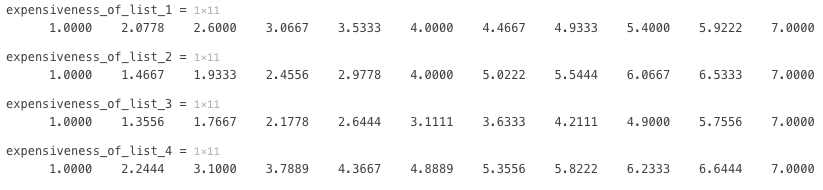

Here I also created a function rft() to calculate the expensiveness (shows in the appendix). 

### **Question 2: Plot graphs to illustrate the predictions.**

v = [28 42 46 49 52 55 58 61 64 68 82; 28 31 34 38 42 55 68 72 76 79 82; ...
    28 29 31 33 36 39 43 48 55 65 82; 28 45 55 62 67 71 74 77 79 81 82];
% Give different color to each curve:
c = [[40,71,92]/255; [74,108,116]/255; [139,166,147]/255; ...
    [240,227,192]/255];

for n = 0:3
    j = v(1 + n,:);
    for i = 1:11
        r(i) = (j(i) - 28) / (82 - 28);
        f(i) = (i - 1) / (11 - 1);
    end
    expen = (0.5*r + 0.5*f)*6 + 1; % The predicted price
    hold on
    plot(expen, '-o', 'Color', c(n + 1,:), 'LineWidth', 2);
    legend('Unimodal', 'Bimodal', 'Positive Skew', ...
        'Negative Skew', 'fontsize', 12);
    xlabel('Position', 'fontsize', 14);
    ylabel('Expensiveness', 'fontsize', 14);
    title('The predicted judged expensiveness', 'fontsize', 14)
    set(legend, 'location', 'northwest')
    hold off
end

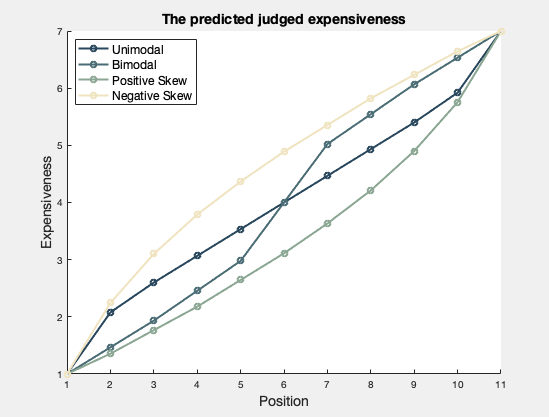

As one can see from the graph, compared to the unimodal list, the items in the bimodal at a lower position (lower than the middle point 6) are subjectively cheaper, the items in the bimodal at a higher position are subjectively more expensive. Compared to the positive skew list, items in the negative skew price list are subjectively more expensive.  

### **Question 3: Explore and briefly describe the effects of varying w.**

Firstly, I use three different values of w to test the effects of varying w on the predicted judged expensiveness.

clf
f = figure;
p = uipanel('Parent', f, 'BorderType', 'none');
p.Title = 'Effects of varying w on predicted judged expensiveness';
p.TitlePosition = 'centertop';
p.FontSize = 14;
p.FontWeight = 'bold';

v = [28 42 46 49 52 55 58 61 64 68 82; 28 31 34 38 42 55 68 72 76 79 82; ...
    28 29 31 33 36 39 43 48 55 65 82; 28 45 55 62 67 71 74 77 79 81 82];
c = [[40,71,92]/255; [74,108,116]/255; [139,166,147]/255; ...
    [240,227,192]/255];
f = 0;

subplot(1, 3, 1, 'Parent', p)
for n = 0:3
    j = v(1 + n,:);
    for i = 1:11
        r(i) = (j(i) - 28) / (82 - 28);
        f(i) = (i - 1) / (11 - 1);
    end
    expen = (0.2*r + 0.8*f)*6 + 1;
    hold on
    plot(expen, '-o', 'Color', c(n + 1,:), 'LineWidth', 2);
    legend('Unimodal', 'Bimodal', 'Positive Skew', ...
        'Negative Skew', 'fontsize', 12);
    xlabel('Position', 'fontsize', 14);
    ylabel('Expensiveness', 'fontsize', 14);
    title('w = 0.2', 'fontsize', 14);
    hold off
end

subplot(1, 3, 2, 'Parent', p)
for n = 0:3
    j = v(1 + n,:);
    for i = 1:11
        r(i) = (j(i) - 28) / (82 - 28);
        f(i) = (i - 1) / (11 - 1);
    end
    expen = (0.5*r + 0.5*f)*6 + 1;
    hold on
    plot(expen, '-o', 'Color', c(n + 1,:), 'LineWidth', 2);
    legend('Unimodal', 'Bimodal', 'Positive Skew', ...
        'Negative Skew', 'fontsize', 12);
    xlabel('Position', 'fontsize', 14);
    ylabel('Expensiveness', 'fontsize', 14);
    title('w = 0.5', 'fontsize', 14);
    hold off
end

subplot(1, 3, 3, 'Parent', p)
for n = 0:3
    j = v(1 + n,:);
    for i = 1:11
        r(i) = (j(i) - 28) / (82 - 28);
        f(i) = (i - 1) / (11 - 1);
    end
    expen = (0.9*r + 0.1*f)*6 + 1;
    hold on
    plot(expen, '-o', 'Color', c(n + 1,:), 'LineWidth', 2);
    legend('Unimodal', 'Bimodal', 'Positive Skew', ...
        'Negative Skew', 'fontsize', 12);
    xlabel('Position', 'fontsize', 14);
    ylabel('Expensiveness', 'fontsize', 14);
    title('w = 0.9', 'fontsize', 14);
    hold off
end

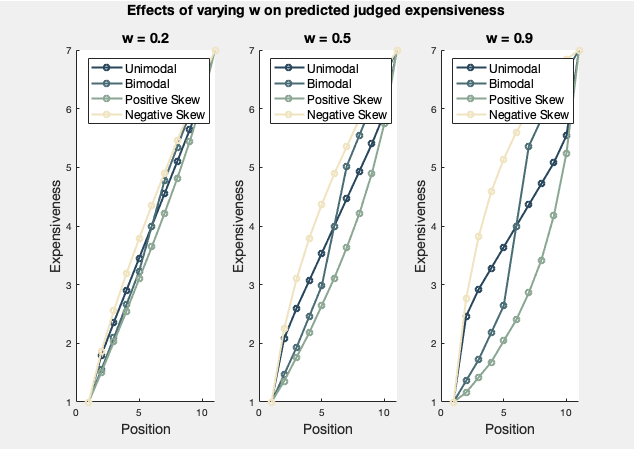

The effects of varying w on each individual price list have also been checked. 

clf
f = figure;
p = uipanel('Parent', f, 'BorderType', 'none');
p.Title = 'Effects of varying w on predicted judged expensiveness';
p.TitlePosition = 'centertop';
p.FontSize = 14;
p.FontWeight = 'bold';

v = [28 42 46 49 52 55 58 61 64 68 82; 28 31 34 38 42 55 68 72 76 79 82; ...
    28 29 31 33 36 39 43 48 55 65 82; 28 45 55 62 67 71 74 77 79 81 82];
c = [[40,71,92]/255; [74,108,116]/255; [139,166,147]/255; ...
    [240,227,192]/255];
f = 0;

subplot(2, 2, 1, 'Parent', p)
j = v(1,:);
for n = 0:3
    w = 0.3:0.2:0.9;
    for i = 1:11
        r(i) = (j(i) - j(1)) / (j(11) - j(1));
        f(i) = (i - 1) / (11 - 1);
    end
    expen = (w(n + 1).*r + (1 - w(n + 1)).*f)*6 + 1;
    hold on
    plot(expen, '-o', 'Color', c(n + 1,:), 'LineWidth', 2);
    legend('w = 0.3', 'w = 0.5', 'w = 0.7', 'w = 0.9', 'fontsize', 12);
    xlabel('Position', 'fontsize', 14);
    ylabel('Expensiveness', 'fontsize', 14);
    title('Unimodal', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold off
end

subplot(2, 2, 2, 'Parent', p)
j = v(2,:);
for n = 0:3
    w = 0.3:0.2:0.9;
    for i = 1:11
        r(i) = (j(i) - j(1)) / (j(11) - j(1));
        f(i) = (i - 1) / (11 - 1);
    end
    expen = (w(n + 1).*r + (1 - w(n + 1)).*f)*6 + 1;
    hold on
    plot(expen, '-o', 'Color', c(n + 1,:), 'LineWidth', 2);
    legend('w = 0.3', 'w = 0.5', 'w = 0.7', 'w = 0.9', 'fontsize', 12);
    xlabel('Position', 'fontsize', 14);
    ylabel('Expensiveness', 'fontsize', 14);
    title('Bimodal', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold off
end

subplot(2, 2, 3, 'Parent', p)
j = v(3,:);
for n = 0:3
    w = 0.3:0.2:0.9;
    for i = 1:11
        r(i) = (j(i) - j(1)) / (j(11) - j(1));
        f(i) = (i - 1) / (11 - 1);
    end
    expen = (w(n + 1).*r + (1 - w(n + 1)).*f)*6 + 1;
    hold on
    plot(expen, '-o', 'Color', c(n + 1,:), 'LineWidth', 2);
    legend('w = 0.3', 'w = 0.5', 'w = 0.7', 'w = 0.9', 'fontsize', 12);
    xlabel('Position', 'fontsize', 14);
    ylabel('Expensiveness', 'fontsize', 14);
    title('Positive skew', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold off
end

subplot(2, 2, 4, 'Parent', p)
j = v(4,:);
for n = 0:3
    w = 0.3:0.2:0.9;
    for i = 1:11
        r(i) = (j(i) - j(1)) / (j(11) - j(1));
        f(i) = (i - 1) / (11 - 1);
    end
    expen = (w(n + 1).*r + (1 - w(n + 1)).*f)*6 + 1;
    hold on
    plot(expen, '-o', 'Color', c(n + 1,:), 'LineWidth', 2);
    legend('w = 0.3', 'w = 0.5', 'w = 0.7', 'w = 0.9', 'fontsize', 12);
    xlabel('Position', 'fontsize', 14);
    ylabel('Expensiveness', 'fontsize', 14);
    title('Negative skew', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold off
end

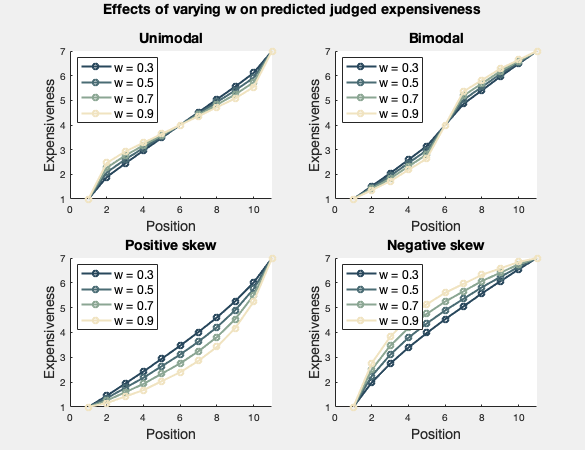

For the high values of w, it gives more weights to the range component, and fewer weights to the frequency component. Therefore, the price which has higher range value will be higher when w increases; the price which has higher frequency value will have less value when w increases. In general, when the value of w is increasing, the curves become steeper. For unimodal and bimodal price lists, the more attractive prices are more attractive along with the increase of w. For the positive skew price list, the prices are more attractive along with the increase of w (the opposite effect on the negative skew price list).  

### **Question 4: Commentary noting any issues arising.**

The application of price based on the Range–Frequency Theory believes that the rated attractiveness of a target price is merely a weighted combination of the range value and relative rank of the price among the whole set of prices. After calculating the weighted range values and relative ranks for each price, I transformed the predicted judged expensiveness to a scale between 1 and 7 (formula: ${\textrm{expensiveness}}_i =\left(w\cdot r_i +\left(1-w\right)\cdot f_i \right)\times 6+1$). 

Here I used four different kinds of price list to test the predicted judged expensiveness: unimodal, bimodal, positive skew and negative skew. Unimodal and bimodal price lists both have the same mean value, which is 55. However, compared to the expensiveness of the prices in the unimodal price list, the prices below the mean value 55 in the bimodal list are much lower, the prices above the mean are higher, which also show in the graph in question two. For positive and negative skew, the prices in the negative skew have higher predicted judged expensiveness compared to the ones in the positive skew price list. 

From the formula, one can see that by varying the parameter w (weights for the range value), the predicted judged expensiveness for each different price also changed. For the high values of w, it gives more weights to the range component, and fewer weights to the frequency component. Therefore, the price which has higher range value will be higher when w increases; the price which has higher frequency value will have less value when w increases. The larger the value of w is, the more extreme the predicted judged expensiveness is (one can see from question three). From experiments and previous research, it shows that the value of parameter w is approximately around 0.5, which means the range value and the relative rank are equally important regarding the contribution to the predicted judged expensiveness. 

The predicted judged expensiveness provides information about the subjective attractiveness of each price for one product. It shows that the predicted judged expensiveness of different prices does not depend on the distance of the mean price and the target price, but the distributions and relative rank of the prices. This statement can be used in consumer goods markets for marketing or advertising. 

When the price stimulation distribution pattern covers both range and frequency changes, the Range-Frequency Theory provides the best explanation of people's preferences for the different price level. However, this theory only focuses on the relationship between the physical stimulation (absolute price) and judged expensiveness, which ignores the intuitions consumers have towards the actual price. 

## Part 3

clear all

### **Question 1: Calculate a serial position curve for a 10-item list.**

We assume items take 1s to present, and recall occurs 1s after the last item.

clf
c = 5; retint = 0;
dist = log([10:-1:1] + retint); % The display of each item

for i = 1:length(dist)
    % The discriminability of each item:
    discrim(i) = 1 / sum(exp(- c*abs(dist(i) - dist)));
    plot(discrim, '-s', 'Color', [40,71,92]/255, 'LineWidth', 2);
    axis([0 length(dist) 0 1]);
    xlabel('Serial Position', 'fontsize', 14);
    ylabel('Discriminability', 'fontsize', 14);
    title('Serial position effect', 'fontsize', 14);
end

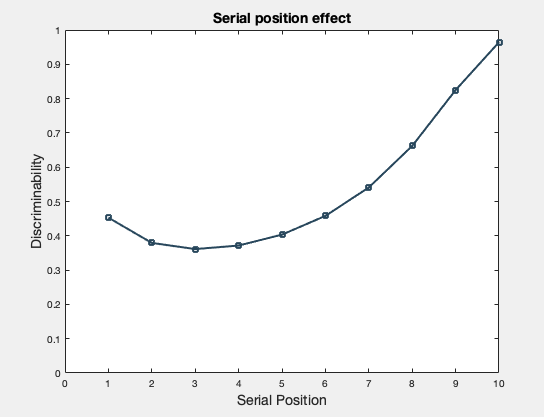

From the graph, we can see that the people can recall the items showed up recently more compared to the items disappeared for a while (recency effect). We can also get the discriminability for each serial position by using the function d (shown in the appendix). 

### **Question 2: What happens to the curve if you add a retention interval?** 

clf
k = [[0,6,35]/255; [40,71,92]/255; [74,108,116]/255; [139,166,147]/255; ...
    [240,227,192]/255];

for n = 1:5
    retint = [0, 3, 5, 8, 10]; c = 5;
    dist = log([10:-1:1] + retint(n));
    for i = 1:length(dist)
        discrim(i) = 1 / sum(exp(- c*abs(dist(i) - dist)));
    end
    plot(discrim,  '-s', 'Color', k(n,:), 'LineWidth', 2);
    legend('Retint = 0', 'Retint = 3', 'Retint = 5', 'Retint = 8', ...
        'Retint = 10', 'fontsize', 12);
    axis([0 length(dist) 0 1]);
    xlabel('Serial Position','fontsize', 14);
    ylabel('Discriminability','fontsize', 14);
    title('Effect of varying retention on serial position', 'fontsize', 14)
    set(legend, 'location', 'northwest')
    hold on
end
hold off

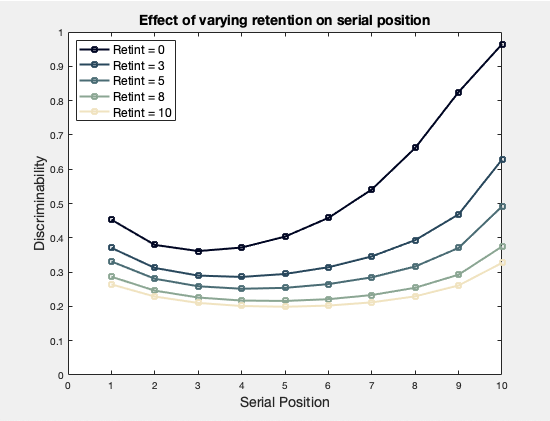

The larger the value of retention is, the flatter the curve of serial position effect will be. This means with the increase of retention, the difficulty of recall each item becomes larger, therefore the discriminability between each item will become weaker (after seeing all the items, if we wait for a period of time and then try to remember the items, it becomes harder to remember each item, and we can easily mix them up). 

### **Question 3: What happens to the curve if you add a temporal gap around one item?**

clf
c = 5; retint = 0;
% Different lists of items:
list = [[10:-1:1]; [12:-1:8 6 4:-1:1]; [18:-1:14 9 4:-1:1]; ...
    [24:-1:20 11 4:-1:1]];
dist = log(list(1,:) + retint);
k = [[40,71,92]/255; [74,108,116]/255; [139,166,147]/255; ...
    [240,227,192]/255];

for n = 0:3
    dist = log(list(1 + n,:) + retint);
    for i = 1:length(dist)
        discrim(i) = 1 / sum(exp(- c*abs(dist(i) - dist)));
    end
    hold on
    plot(discrim,  '-s', 'Color', k(n + 1,:), 'LineWidth', 2);
    axis([0 length(dist) 0 1]);
    legend('No Temporal Gaps', 'With A Small Gap', 'With A Medium Gap', ...
        'With A Large Gap', 'fontsize', 12);
    xlabel('Serial Position', 'fontsize', 14);
    ylabel('Discriminability', 'fontsize', 14);
    title('Effect of temporal gaps on serial position', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold off
end

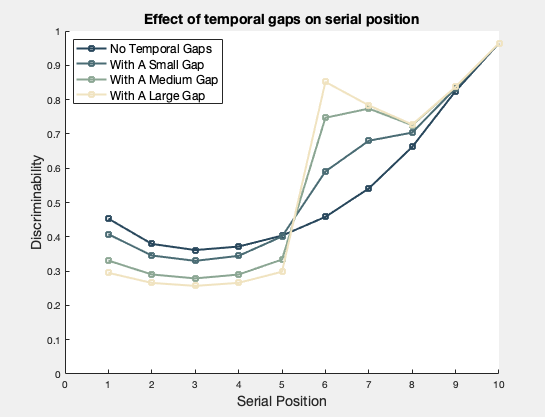

As we can see from the graph if we add a gap starts at position 5, the serial position effect changes. More specifically, the discriminability of items increases after the starting point of the gap, while decreases for the ones before the gap starts. The larger the gap is (the longer the time pause), the more distinguishable of the items within the gap. In reality, this means if there is a larger time gap in between the appearances of items, the items showed before the gap will become even harder for people to remember, while the items showed after the gap will become easier to remember or distinguish from the rest. 

### **Question 4: What happens if you change the list length / the c parameter? **

clf
f = figure;
p = uipanel('Parent', f, 'BorderType', 'none');
p.Title = 'Serial position effect';
p.TitlePosition = 'centertop';
p.FontSize = 14;
p.FontWeight = 'bold';

subplot(1, 2, 1, 'Parent', p);
% Effect of varying the list length:
k = [[40,71,92]/255; [74,108,116]/255; [139,166,147]/255; ...
    [240,227,192]/255];
c = 5; retint = 0;
for n = 1:4
    m = 10:5:25;
    dist = log([m(n):-1:1] + retint);
    for i = 1:length(dist)
        discrim(i) = 1 / sum(exp(- c*abs(dist(i) - dist)));
    end
    hold on
    plot(discrim,  '-s', 'Color', k(n,:), 'LineWidth', 2);
    xlabel('Serial Position', 'fontsize', 14);
    ylabel('Discriminability', 'fontsize', 14);
    legend('Length = 10', 'Length = 15', 'Length = 20', ...
        'Length = 25', 'fontsize', 12);
    title('Effect of varying the list length', 'fontsize', 14);
    set(legend, 'location', 'northwest')
    hold off
end

subplot(1, 2, 2, 'Parent', p);
% Effect of varying the c parameter:
k = [[40,71,92]/255; [74,108,116]/255; [139,166,147]/255; ...
    [240,227,192]/255];
retint = 0;
for n = 1:4
    c = [1, 3, 6, 9];
    dist = log([10:-1:1]);
    for i = 1:length(dist)
        discrim(i) = 1 / sum(exp(- c(n).*abs(dist(i) - dist)));
    end
    hold on
    plot(discrim,  '-s', 'Color', k(n,:), 'LineWidth', 2);
    axis([0 length(dist) 0 1]);
    xlabel('Serial Position', 'fontsize', 14);
    ylabel('Discriminability', 'fontsize', 14);
    legend('c = 1', 'c = 3', 'c = 6', 'c = 9', 'c = 10', 'fontsize', 12);
    title('Effect of varying the c parameter', 'fontsize', 14)
    set(legend, 'location', 'northwest')
    hold off
end

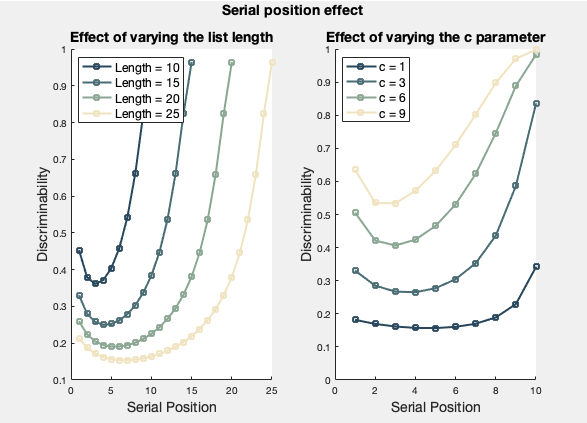

From the graph, we can see that when the length of the list increases, the average discriminability decreases. In reality, it means when the items we need to remember increases, for each item it will become more difficult to remember and distinguish. As we can see, when the parameter c decreases, the graph becomes very flat. As c is a free parameter that governs the rate at which similarity reduces with distance, therefore when c decreases, the difference between each item becomes smaller and smaller (the items are more similar to each other), and it is more difficult to distinguish each item with time passing by.

### **Question 5: Commentary noting any issues arising.**

As we know, the serial position effect is the tendency of a person to recall the first and last items in a series best, and the middle items worst (formula: $\mathrm{discrim}=\frac{1}{\mathrm{sum}\left(e^{-c\times d_{i,j} } \right)}$). The longer the length of the series of items is, the harder it is for people to recall the items. 

In the serial position effect, one thing that catches my eyes was that the last few items have a very high value of discriminability - recency effect. The recency effect refers to cognitive biases in which the last stimuli or informational memory are too compelling. For example, a driver saw the same red and blue cars on a highway trip, but if he saw a red car at the next high speed, he would think he saw a lot of red cars on the trip. 

However, instead of letting people recall the items right after they observe them, if we have retention, the results will be different. In general, the longer the retention is, the more difficult it becomes for people to recall the items, and the items will also become very hard to distinguish. Therefore the recency effect disappears (shows in the figure of question two). People have a limited shortage of short-term memory. For instance, when you try to remember a phone number, if you didn't immediately recall the number, after just a few seconds, you could not remember it correctly. 

Moreover, if we add temporal gaps in between the items, it also affects the recency effect. By adding a temporal time gap, the items showed within the gap become more memorable for people. So people will recall more of the items within the temporal time gap, which means the recency effect disappears. On the opposite side, the items showed before the gap will become harder for people to recall. Similarly, by varying the parameter c, the recency effects disappear along with the decrease of the value of parameter c. Here the parameter c measures the rate at which similarity reduces with distance, therefore when c is small, and the items are very similar to each other, the significance level of both the primary effect and recency effect decreases. 

We can also apply the serial position effect into real life. Serial position effects imply that people's first and last impression of you matters the most when it comes to socialisation. If you want people to remember your achievement in a workplace, it is better to show your hard work at the beginning of your career or the end of an important project season. Another thing to mention here is, in the recall experiment, after the information is presented, an inverse operation is added before the beginning of the recall (one example can be adding the temporal gaps into the list of items as mentioned before), the recency effect disappears. This becomes the proof of the dual memory theory. 

## Part 4

clear all

### **Question 1: Schelling segregation model.**

In the Schelling segregation model below, I use white colour to represent psychologists, black colour to represent economists. Moreover, I also created a function Schelling (in the appendix). 

clf
ssmodel_video = VideoWriter('ssmodel_video.avi');
video.FrameRate = 2;
open(ssmodel_video);
numframes = 100; nside = 50;
randworld = rand(nside, nside);
world = randworld > 0.5;
colormap([1 1 1; 0 0 0]);
numsadecons = 100; numsadpsychs = 100;
% Calculate statistical data for the plots later:
totalpeople = nside*nside; % Total population
numsecon = sum(sum(world)); % Numbers of economists
numspsych = totalpeople - numsecon; % Numbers of psychologists
numssadppl = []; % Numbers of sad people in total
numsimilar = []; % Numbers of people with the same category around you
count = 0;

for i = 1:numframes
    while (numsadecons > 50) && (numsadpsychs > 50)
        % All the economists around you:
        A = circshift(world, [1, 0]); B = circshift(world, [-1, 0]);
        C = circshift(world, [0, 1]); D = circshift(world, [0, -1]);
        necon = A + B + C + D;
        sadecons = world.*((world.*necon) < 3);
        sadpsychs = abs(world - 1).*((abs(world - 1).*necon) > 1);
        numsadecons = sum(sum(sadecons));
        numsadpsychs = sum(sum(sadpsychs));
        [r,c] = find(sadecons);
        index = ceil(rand*numsadecons);
        world(r(index), c(index)) = 0;
        [r,c] = find(sadpsychs);
        index = ceil(rand*numsadpsychs);
        % Switch with a random sad person in the opposite
        % category.
        world(r(index), c(index)) = 1;
        numssadppl = [numssadppl; [numsadecons, numsadpsychs]];
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section first to get the plots to get
        % the plots of the movements.
        % Show the percentage of sad people in the
        % model:
        x = 1:length(numssadppl);
        percentsadecons = (numssadppl(:,1)/totalpeople)*100;
        percentsadpsychs = (numssadppl(:,2)/totalpeople)*100;
        percentsadppl = ((numssadppl(:,1) + numssadppl(:,2))/totalpeople)*100;
        subplot(1, 2, 1)
        p1 = plot(x, percentsadecons, x, percentsadpsychs, x, percentsadppl, ...
            ':', 'LineWidth', 3);
        legend('%Sad Economists', '%Sad Psychologists', '%Sad People', ...
            'fontsize', 12)
        set(legend, 'location', 'northwest')
        title('Unhappy people (%)', 'fontsize', 14)
        ylabel('Unhappy People (%)', 'fontsize', 14)
        xlabel(sprintf('Number Of Rounds (%d)', count), 'fontsize', 14)
        ylim([0 100])
        % Show the percentage of the same type of people
        % in the neighbourhoods:
        secon = sum(sum(necon.*world));
        spsy = sum(sum((4 - necon).*abs(world - 1)));
        numsimilar = [numsimilar; [secon, spsy]];
        s = 1:length(numsimilar);
        percentsecon = (numsimilar(:,1)/(4*totalpeople))*100;
        percentspsych = (numsimilar(:,2)/(4*totalpeople))*100;
        percentsppl = ((numsimilar(:,1) + ...
            numsimilar(:,2))/(4*totalpeople))*100;
        subplot(1, 2, 2)
        p2 = plot(s, percentsecon, s, percentspsych, s, percentsppl, ...
            ':', 'LineWidth', 3);
        legend('%Similar Economists', '%Similar Psychologists', ...
            '%Similar People', 'fontsize', 12)
        set(legend, 'location', 'northwest')
        title('Similar neighbours (%)', 'fontsize', 14)
        ylabel('Similar Neighbours (%)', 'fontsize', 14)
        xlabel(sprintf('Number Of Rounds (%d)', count), 'fontsize', 14)
        ylim([0 100])
        count = count + 1;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section to get the image of the model:
        subplot(1, 1, 1)
        imagesc(world); pause(0.01);
        frame = getframe;
        writeVideo(ssmodel_video, frame);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section for the later table:
        percantage_sad_econ1 = sprintf('%2.2f%%', (numsadecons/numsecon)*100);
        percentage_sad_psy1 = sprintf('%2.2f%%', (numsadpsychs/numspsych)*100);
        percentage_sad1 = sprintf('%2.2f%%', ((numsadecons + numsadpsychs)/...
            totalpeople)*100);
        ratio_of_sad_econ_to_psy1 = roundn(numsadecons/numsadpsychs, -2);
    end
end

close(ssmodel_video)

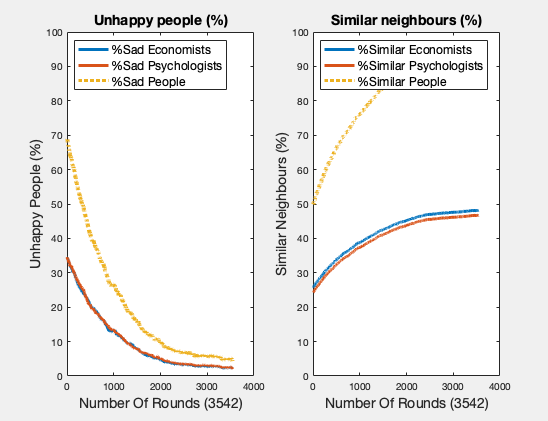

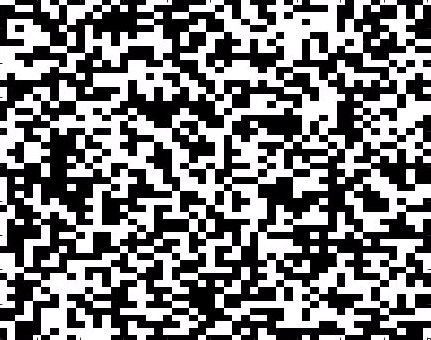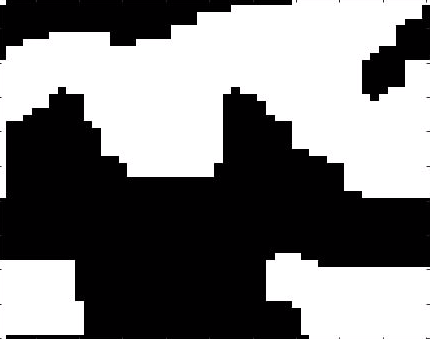

The movements of this model have been saved in the video [ssmodel_video_link](https://drive.google.com/file/d/1cZcdRlbIBjcLB2b16qtyrhi0kTXd800S/view?usp=sharing). In the final result of the model (right corner), we can see that after gathering, economists and psychologists are in different clusters. From the graph (upper left) we can observe that along with the time changing, the proportion of unhappy people drastically dropped. On the other hand, because of segregation through time, the similarity among the neighbourhood also increased till it reaches its maximum when almost everyone in this world is happy (upper right). Besides, because of the proportion of economists and psychologists are the same in this model, the changing of percentage in both unhappy people and similarity for economists and psychologists are the same. 

### Question 2: Change tolerance level and proportion of agents. 

Here I have made a few changes to extend the model. Firstly, other than having an equal amount of economists and psychologists, there are more economists than psychologists (the ratio between psychologists and economists is 2:3). Secondly, both economists and psychologists can tolerate two different neighbours now. 

clf
ssmodel_moreeco_video = VideoWriter('ssmodel_moreeco_video.avi');
video.FrameRate = 2;
open(ssmodel_moreeco_video);
numframes = 100; nside = 50;
randworld = rand(nside, nside);
% More economists (60%) than psychologists (40%):
world = randworld > 0.4;
colormap([1 1 1; 0 0 0]);
numsadecons = 100; numsadpsychs = 100;
totalpeople = nside*nside;
numsecon = sum(sum(world));
numspsych = totalpeople - numsecon;
numssadppl = [];
numsimilar = [];
count = 0;

for i = 1:numframes
    while (numsadecons > 50) && (numsadpsychs > 50)
        A = circshift(world, [1, 0]); B = circshift(world, [-1, 0]);
        C = circshift(world, [0, 1]); D = circshift(world, [0, -1]);
        necon = A + B + C + D;
        % Both economists and psychologists can tolerate 2 different
        % neighbours:
        sadecons = world.*((world.*necon) < 2);
        sadpsychs = abs(world - 1).*((abs(world - 1).*necon) > 2);
        numsadecons = sum(sum(sadecons));
        numsadpsychs = sum(sum(sadpsychs));
        [r,c] = find(sadecons);
        index = ceil(rand*numsadecons);
        world(r(index), c(index)) = 0;
        [r,c] = find(sadpsychs);
        index = ceil(rand*numsadpsychs);
        world(r(index), c(index)) = 1;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section first to get the plots to get
        % the plots of the movements.
        numssadppl = [numssadppl; [numsadecons, numsadpsychs]];
        x = 1:length(numssadppl);
        percentsadecons = (numssadppl(:,1)/totalpeople)*100;
        percentsadpsychs = (numssadppl(:,2)/totalpeople)*100;
        percentsadppl = ((numssadppl(:,1) + numssadppl(:,2))/totalpeople)*100;
        subplot(1, 2, 1)
        p1 = plot(x, percentsadecons, x, percentsadpsychs, x, percentsadppl, ...
            ':', 'LineWidth', 3);
        legend('%Sad Economists', '%Sad Psychologists', '%Sad People', ...
            'fontsize', 12)
        set(legend, 'location', 'northwest')
        title('Unhappy people (%)', 'fontsize', 14)
        ylabel('Unhappy People (%)', 'fontsize', 14)
        xlabel(sprintf('Number Of Rounds (%d)', count), 'fontsize', 14)
        ylim([0 100])
        secon = sum(sum(necon.*world));
        spsy = sum(sum((4 - necon).*abs(world - 1)));
        numsimilar = [numsimilar; [secon, spsy]];
        s = 1:length(numsimilar);
        percentsecon = (numsimilar(:,1)/(4*totalpeople))*100;
        percentspsych = (numsimilar(:,2)/(4*totalpeople))*100;
        percentsppl = ((numsimilar(:,1) + ...
            numsimilar(:,2))/(4*totalpeople))*100;
        subplot(1, 2, 2)
        p2 = plot(s, percentsecon, s, percentspsych, s, percentsppl, ...
            ':', 'LineWidth', 3);
        legend('%Similar Economists', '%Similar Psychologists', ...
            '%Similar People', 'fontsize', 12)
        set(legend, 'location', 'northwest')
        title('Similar neighbours (%)', 'fontsize', 14)
        ylabel('Similar Neighbours (%)', 'fontsize', 14)
        xlabel(sprintf('Number Of Rounds (%d)', count), 'fontsize', 14)
        ylim([0 100])
        count = count + 1;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section to get the image of the model:
        subplot(1, 1, 1)
        imagesc(world); pause(0.01);
        frame = getframe;
        writeVideo(ssmodel_moreeco_video, frame);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section for the later table:
        percantage_sad_econ2 = sprintf('%2.2f%%', (numsadecons/numsecon)*100);
        percentage_sad_psy2 = sprintf('%2.2f%%', (numsadpsychs/numspsych)*100);
        percentage_sad2 = sprintf('%2.2f%%', ((numsadecons + numsadpsychs)/...
            totalpeople)*100);
        ratio_of_sad_econ_to_psy2 = roundn(numsadecons/numsadpsychs, -2);
    end
end

close(ssmodel_moreeco_video)

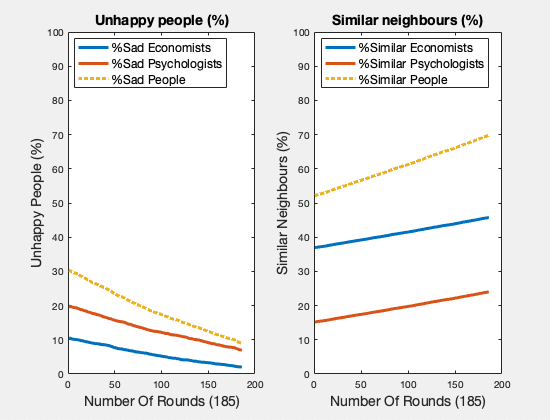

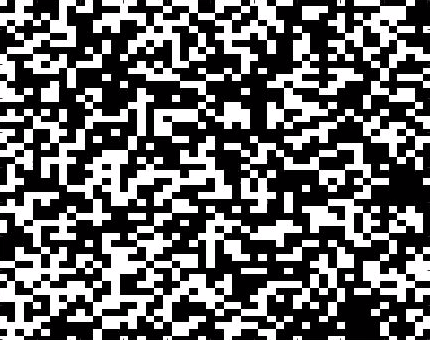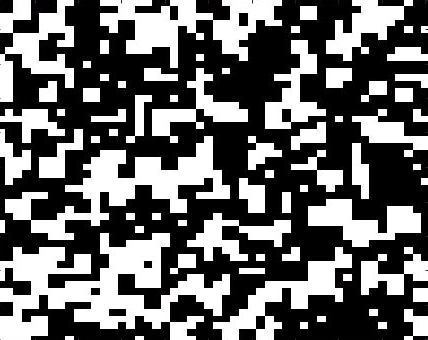

As we can see, (video clip [ssmodel_moreeco_video_link](https://drive.google.com/file/d/1RExGYZeIPcmrPA7wnyIivAHP8dSzrUmC/view?usp=sharing)), when we put more economists in the world, it is easier for unhappy economists to move and find their "own people", so the process for them to be happy becomes shorter. Moreover, after I loosen up the restrictions, the conditions for economists and psychologists to be happy become easier to achieve. Therefore, the whole process becomes much faster compared to the original model in question one (the number of rounds here is only 185). However, the final result of the model is not as "good" as before (right corner), the similarity of neighbours, in this case, is only about 70% at the end of the segregation (upper right). 

### **Question 3: Look at larger neighbourhoods.**

In this question, I extended the neighbourhoods to double the size as before (the original version). 

clf
ssmodel_large_video = VideoWriter('ssmodel_large_video.avi');
video.FrameRate = 2;
open(ssmodel_large_video);
numframes = 100; nside = 50;
randworld = rand(nside, nside);
world = randworld > 0.5;
colormap([1 1 1; 0 0 0]);
numsadecons = 200; numsadpsychs = 200;
totalpeople = nside*nside;
numsecon = sum(sum(world));
numspsych = totalpeople - numsecon;
numssadppl = [];
numsimilar = [];
count = 0;

for i = 1:numframes
    while (numsadecons > 100) && (numsadpsychs > 100)
        A = circshift(world, [1, 0]); B = circshift(world, [-1, 0]);
        C = circshift(world, [0, 1]); D = circshift(world, [0, -1]);
        % Extend the neighbourhoods to double the size:
        E = circshift(world, [1, 1]); F = circshift(world, [-1, 1]);
        G = circshift(world, [1, -1]); H = circshift(world, [-1, -1]);
        necon = A + B + C + D + E + F + G + H;
        % Both the tolerance level for economists and psychologists
        % also doubled correlated to the larger
        % neighbourhood: 
        sadecons = world.*((world.*necon) < 6);
        sadpsychs = abs(world - 1).*((abs(world - 1).*necon) > 2);
        numsadecons = sum(sum(sadecons));
        numsadpsychs = sum(sum(sadpsychs));
        [r,c] = find(sadecons);
        index = ceil(rand*numsadecons);
        world(r(index),c(index)) = 0;
        [r,c] = find(sadpsychs);
        index = ceil(rand*numsadpsychs);
        world(r(index),c(index)) = 1;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section first to get the plots to get
        % the plots of the movements.
        numssadppl = [numssadppl; [numsadecons, numsadpsychs]];
        x = 1:length(numssadppl);
        percentsadecons = (numssadppl(:,1)/totalpeople)*100;
        percentsadpsychs = (numssadppl(:,2)/totalpeople)*100;
        percentsadppl = ((numssadppl(:,1) + numssadppl(:,2))/totalpeople)*100;
        subplot(1, 2, 1)
        p1 = plot(x, percentsadecons, x, percentsadpsychs, x, percentsadppl, ...
            ':', 'LineWidth', 3);
        legend('%Sad Economists', '%Sad Psychologists', '%Sad People', ...
            'fontsize', 12)
        set(legend, 'location', 'northwest')
        title('Unhappy people (%)', 'fontsize', 14)
        ylabel('Unhappy People (%)', 'fontsize', 14)
        xlabel(sprintf('Number Of Rounds (%d)', count), 'fontsize', 14)
        ylim([0 100])
        secon = sum(sum(necon.*world));
        % Now we have 8 neighbours, change the value 4
        % into 8:
        spsy = sum(sum((8 - necon).*abs(world - 1)));
        numsimilar = [numsimilar; [secon, spsy]];
        s = 1:length(numsimilar);
        percentsecon = (numsimilar(:,1)/(8*totalpeople))*100;
        percentspsych = (numsimilar(:,2)/(8*totalpeople))*100;
        percentsppl = ((numsimilar(:,1) + ...
            numsimilar(:,2))/(8*totalpeople))*100;
        subplot(1, 2, 2)
        p2 = plot(s, percentsecon, s, percentspsych, s, percentsppl, ...
            ':', 'LineWidth', 3);
        legend('%Similar Economists', '%Similar Psychologists', ...
            '%Similar People', 'fontsize', 12)
        set(legend, 'location', 'northwest')
        title('Similar neighbours (%)', 'fontsize', 14)
        ylabel('Similar Neighbours (%)', 'fontsize', 14)
        xlabel(sprintf('Number Of Rounds (%d)',count), 'fontsize', 14)
        ylim([0 100])
        count = count + 1;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section to get the image of the model:
        subplot(1, 1, 1)
        imagesc(world); pause(0.1);
        frame = getframe;
        writeVideo(ssmodel_large_video, frame);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section for the later table:
        percantage_sad_econ3 = sprintf('%2.2f%%', (numsadecons/numsecon)*100);
        percentage_sad_psy3 = sprintf('%2.2f%%', (numsadpsychs/numspsych)*100);
        percentage_sad3 = sprintf('%2.2f%%', ((numsadecons + numsadpsychs)/...
            totalpeople)*100);
        ratio_of_sad_econ_to_psy3 = roundn(numsadecons/numsadpsychs, -2);
    end
end

close(ssmodel_large_video)

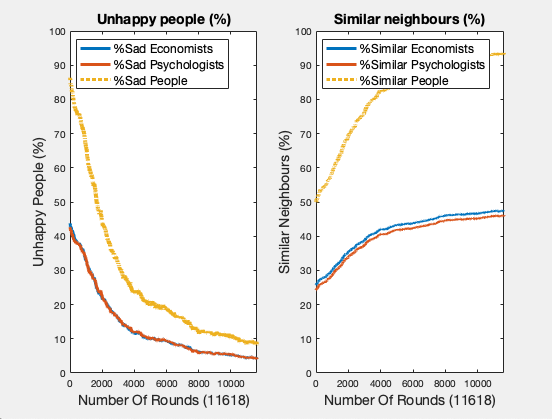

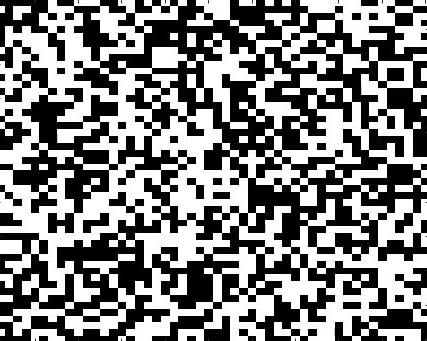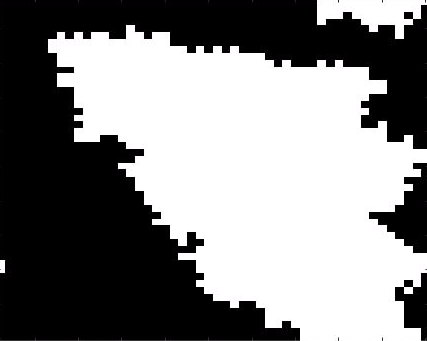

As we can see (video clip [ssmodel_large_video_link](https://drive.google.com/file/d/1V_67i5sobbTLRLnvZABouhlZYD8qUo9d/view?usp=sharing)), with the increase of the size of the neighbourhoods (double the size of the original neighbourhoods), the process for economists and psychologists to be happy also becomes longer (it takes longer for economists and psychologists to gather together and eventually surround by their "own people"). More specifically, from the graphs, one can observe that firstly, the amount of time it needs to get to the final stage of the model is 11618 rounds, which is much more than the rounds of the original model. The curves of the changing of both percentages of sad people and similar neighbours are similar to the ones of the original model, other than the fact the curves have slightly more fluctuations in this case. 

### **Question 4: Only allow adjacent neighbours to switch.**

clf
ssmodel_neigh_video = VideoWriter('ssmodel_neigh_video.avi');
video.FrameRate = 2;
open(ssmodel_neigh_video);
numframes = 100;
nside = 25; % Reduce the size to half
randworld = rand(nside, nside);
world = randworld > 0.5;
colormap([1 1 1; 0 0 0]);
numsadecons = 50; numsadpsychs = 50; % Reduce the number of sad people accordingly
totalpeople = nside*nside;
numsecon = sum(sum(world));
numspsych = totalpeople - numsecon;
numssadppl = [];
numsimilar = [];
count = 0;

for i = 1:numframes
    while (numsadecons > 25) && (numsadpsychs > 25) % Lower down the restraints as well
        A = circshift(world, [1, 0]); B = circshift(world, [-1, 0]);
        C = circshift(world, [0, 1]); D = circshift(world, [0, -1]);
        necon = A + B + C + D;
        sadecons = world.*((world.*necon) < 3);
        sadpsychs = abs(world - 1).*((abs(world - 1).*necon) > 1);
        numsadecons = sum(sum(sadecons));
        numsadpsychs = sum(sum(sadpsychs));
        [r, c] = find(sadecons);
        index = ceil(rand*numsadecons);
        % Find the unhappy psychologists around the
        % economists:
        loc_sadeco = [r(index), c(index)]; % Locate one sad economist
        [rpsy, cpsy] = find(sadpsychs);
        loc_sadpsy = [rpsy, cpsy]; % Locate one sad psychologist
        % Find k-nearest neighbours in x for every query point in y, k =
        % 1:
        [x, y] = knnsearch(loc_sadpsy, loc_sadeco, 'k', 1);
        % Only allow unhappy people to switch with their
        % unhappy neighbours (if there is any):
        if y == 1
            swit = loc_sadpsy(x,:);
            % Switching with your unhappy neighbour:
            world(swit(1), swit(2)) = 1;
            world(r(index), c(index)) = 0;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section first to get the plots to get
        % the plots of the movements.
        numssadppl = [numssadppl; [numsadecons, numsadpsychs]];
        x = 1:length(numssadppl);
        percentsadecons = (numssadppl(:,1)/totalpeople)*100;
        percentsadpsychs = (numssadppl(:,2)/totalpeople)*100;
        percentsadppl = ((numssadppl(:,1) + numssadppl(:,2))/totalpeople)*100;
        subplot(1, 2, 1)
        p1 = plot(x, percentsadecons, x, percentsadpsychs, x, percentsadppl, ...
            ':', 'LineWidth', 3);
        legend('%Sad Economists', '%Sad Psychologists', '%Sad People', ...
            'fontsize', 12)
        set(legend, 'location', 'northwest')
        title('Unhappy people (%)', 'fontsize', 14)
        ylabel('Unhappy People (%)', 'fontsize', 14)
        xlabel(sprintf('Number Of Rounds (%d)', count), 'fontsize', 14)
        ylim([0 100])
        secon = sum(sum(necon.*world));
        spsy = sum(sum((4 - necon).*abs(world - 1)));
        numsimilar = [numsimilar; [secon, spsy]];
        s = 1:length(numsimilar);
        percentsecon = (numsimilar(:,1)/(4*totalpeople))*100;
        percentspsych = (numsimilar(:,2)/(4*totalpeople))*100;
        percentsppl = ((numsimilar(:,1) + ...
            numsimilar(:,2))/(4*totalpeople))*100;
        subplot(1, 2, 2)
        p2 = plot(s, percentsecon, s, percentspsych, s, percentsppl, ...
            ':', 'LineWidth', 3);
        legend('%Similar Economists', '%Similar Psychologists', ...
            '%Similar People', 'fontsize', 12)
        set(legend, 'location', 'northwest')
        title('Similar neighbours (%)', 'fontsize', 14)
        ylabel('Similar Neighbours (%)', 'fontsize', 14)
        xlabel(sprintf('Number Of Rounds (%d)', count), 'fontsize', 14)
        ylim([0 100])
        count = count + 1;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section to get the image of the model:
        subplot(1, 1, 1)
        imagesc(world); pause(0.001);
        frame = getframe;
        writeVideo(ssmodel_neigh_video, frame);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Use this section for the later table:
        percantage_sad_econ4 = sprintf('%2.2f%%', (numsadecons/numsecon)*100);
        percentage_sad_psy4 = sprintf('%2.2f%%', (numsadpsychs/numspsych)*100);
        percentage_sad4 = sprintf('%2.2f%%', ((numsadecons + numsadpsychs)/...
            totalpeople)*100);
        ratio_of_sad_econ_to_psy4 = roundn(numsadecons/numsadpsychs, -2);
    end
end

close(ssmodel_neigh_video)

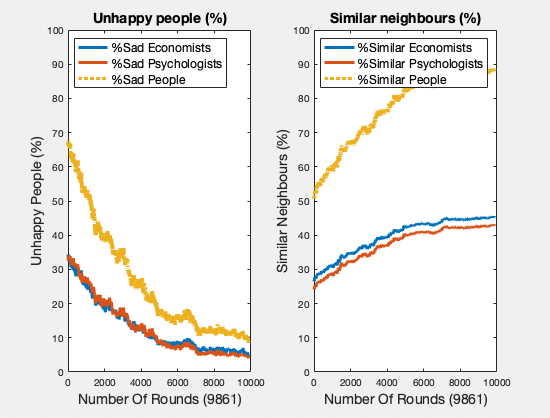

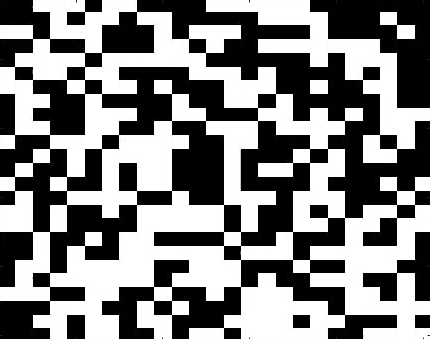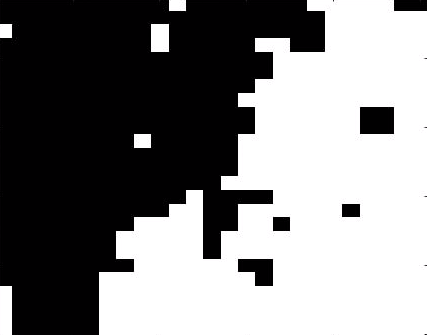

As we can see ([ssmodel_neigh_video_link](https://drive.google.com/file/d/1zI6IHFPVSIfGBK1Qdj3GyozXrEss2Lki/view?usp=sharing)), we only allow adjacent neighbours to switch (if you are unhappy, you can only switch with unhappy people around you). Therefore, a reasonable prediction is that the process for economists and psychologists to be happy becomes much longer compared to the cases in previous questions. In this case, I reduce the size of the world and population to speed up the process. Specifically, we can see that the number of rounds, in this case, is 9861. The percentage of the sad people is decreasing unsmoothly compared to any other previous cases (upper left). Moreover, the curves for the trends of similarities for the neighbourhoods is also not increasing as smooth as before (upper right). 

### Question 5: Table of statistics

% Store all the data from previous questions:
k = {'Original', percantage_sad_econ1, percentage_sad_psy1,...
    percentage_sad1, ratio_of_sad_econ_to_psy1; ...
    'More Economist&Tolerance', percantage_sad_econ2, percentage_sad_psy2, ...
    percentage_sad2, ratio_of_sad_econ_to_psy2; ...
    'Larger Neighbourhood', percantage_sad_econ3, percentage_sad_psy3, ...
    percentage_sad3, ratio_of_sad_econ_to_psy3; ...
    'Only Switch With Neighbours', percantage_sad_econ4, percentage_sad_psy4, ...
    percentage_sad4, ratio_of_sad_econ_to_psy4};

T = cell2table(k, 'VariableNames',{'Case', 'Sad_economist', 'Sad_psychologist', ...
    'Sad_people', 'Ratio_of_sadeconomist_over_sadpsychologist'})

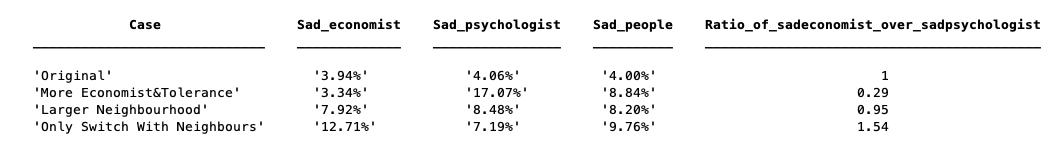

From the table, we can see that when we have more economists in the world, psychologists are surrounded by more economists, so the percentage of sad psychologists is larger. When people can only switch with their neighbours, the percentage of sad people at the final stage is the largest. For the more massive neighbourhood case, all the percentages are approximately double the size of the ones in the original model. All of these statistics correspond with the graphs and the images in previous questions. 

### **Question 6: Commentary noting any issues arising.**

The Schelling-style model shows how local interactions can lead to surprising aggregate structure. In particular, it shows that relatively mild preference for neighbours of similar "taste" can lead in aggregate to the collapse of mixed neighbourhoods, and high levels of segregation — for instance, these wealthy suburbs and Chinatown in the United States. In this model, each individual has a threshold for the heterogeneous composition of his or her surroundings. If this preference is achieved, the individual will remain in the current environment; if this preference is not fulfilled, the individual will choose to leave until the environment is satisfied. The simulation results of the isolated dynamic model show that even if everyone does not have racial discrimination or discrimination based on other social characteristics, but only hopes that they do not become a minority, it will always bring about the consequences of social isolation. 

As one can see from the original model in question one, once people set up their preferences, the segregation begins. Throughout the whole process, the percentage of unsatisfied people decreases, and the similarity among the neighbourhoods increases. If there are only an equal amount of economists and psychologists in the world, both economists and psychologists have the same trends of the percentage changing. However, if the number of economists and psychologists are not equal, they will have different curves towards the changing in the percentage of unsatisfied people and the similarity of the neighbourhoods. 

If people's preferences change (which means the tolerance level changes), the segregation process will also become different, as we can see the result in question two. In general, the more "open-minded" people are (high tolerance level), the less segregated the society will become. At the final stage of the model, there will be less significant clusters in the world. The similarity within neighbourhoods will also decrease. The whole segregating process will take less time as well. 

In order to make the model more realistic, I also double the size of the neighbourhood by adding four more directions to the world map in the model (in question three). By doing so, the amount of time for people to be around their "own" people and be happy significantly increased. However, the final stage of the model is similar to the original model, the only difference here is that one group of agents are gathered around the edges. 

Moreover, I added another restriction that people can only adjacent with their neighbours (question four). Under this condition, it takes much longer for the agents in the world to be satisfied. One interesting thing here is that trends of the changing of the percentage of unhappy people and the similarity of the neighbourhood are both not as smooth as previous cases. Also, the similarity at the final stage is also not as high as the original model.   

To conclude, the Schelling model points out a process of emergent order that may be quite common in social action. Overall, on the average in the whole population, there is no particular tendency toward segregation. However, as individual agents follow simple rules under local circumstances (preferences), local patterns emerge. Once local patterns emerge, they affect the actions of other people, resulting in a "cascade" of movement.  Collective action and social movements, diffusion of fads, fashion, and information, and other growth and diffusion processes may depend critically not on the attributes of the agents, but rather on the "coupling topology" or patterns of social distance among them. The more elements and variations we can put in the model, the closer it can be to the real-life situation. The Schelling model is not a complete theory of residential segregation. However, it offers some interesting insights into how unexpected patterns may emerge out of the interaction, even when the people are unaware and do not intend for such outcomes at the beginning. 

## Appendix

### Part 1: Function calcu

function rmsd = calcu(V)
k = V(1); a = V(2);
i = 2:2:12;
data = [1.1 1.5 2.1 2.5 2.9 3.2];
SS = k*(i.^a);
sd = (SS-data).^2;
rmsd = sqrt(mean(sd));
end

% Use this function to find the values of a and k when
% RMSD reaches the minimum value:
h = fminsearch('calcu', [0 0])

h =     0.6661    0.6341


### Part 2: Function rft

% Unimodal:
v1 = [28 42 46 49 52 55 58 61 64 68 82];
% Bimodal:
v2 = [28 31 34 38 42 55 68 72 76 79 82];
% Positive skew:
v3 = [28 29 31 33 36 39 43 48 55 65 82];
% Negative skew:
v4 = [28 45 55 62 67 71 74 77 79 81 82];

function expen = rft(v)
i = 1:11;
r = (v(i) - v(1)) / (v(11) - v(1));
f = (i - 1) / (11 - 1);
expen = (0.5*r + 0.5*f)*6 + 1;
end

rft(v1);
rft(v2);
rft(v3);
rft(v4);

### Part 3: Function d

function discrim = d(dist)
c = 5; retint = 0;
dist = log([10:-1:1] + retint);
% Her we can change the values of c / retint or the
% length of the dist to see different effects on the
% serial position.
for i = 1: length(dist)
    discrim(i) = 1 / sum(exp(-c*abs(dist(i) - dist)));
end
plot(discrim, '-s', 'Color', [40,71,92]/255, 'LineWidth', 2);
axis([0 length(dist) 0 1]);
xlabel('Serial Position', 'fontsize', 14);
ylabel('Discriminability', 'fontsize', 14);
title('Serial Position Effect', 'fontsize', 14);
set(gcf, 'color', 'white')
end

### Part 4: Function Schelling

function [necon, sadecons, sadpsychs] = Schelling(nside, numsadecons, numsadpsychs, world)
colormap([1 1 1; 0 0 0]);
while (numsadecons > 50) && (numsadpsychs > 50)
    A = circshift(world, [1, 0]); B = circshift(world, [-1, 0]);
    C = circshift(world, [0, 1]); D = circshift(world, [0, -1]);
    necon = A + B + C + D;
    % Extend the neighbourhoods to double the size:
    % E = circshift(world, [1, 1]); F = circshift(world, [-1, 1]);
    % G = circshift(world, [1, -1]); H = circshift(world, [-1, -1]);
    % necon = A + B + C + D + E + F + G + H;
    sadecons = world.*((world.*necon) < 3);
    sadpsychs = abs(world - 1).*((abs(world - 1).*necon) > 1);
    % For the model in question two:
    % sadecons = world.*((world.*necon) < 2);
    % sadpsychs = abs(world - 1).*((abs(world - 1).*necon) > 2);
    numsadecons = sum(sum(sadecons)); numsadpsychs = sum(sum(sadpsychs));
    [r, c] = find(sadecons);
    index = ceil(rand*numsadecons);
    world(r(index), c(index)) = 0;
    [r,c] = find(sadpsychs);
    index = ceil(rand*numsadpsychs);
    world(r(index), c(index)) = 1;
    % For the fourth question:
    % loc_sadeco = [r(index), c(index)];
    % [rpsy, cpsy] = find(sadpsychs);
    % loc_sadpsy = [rpsy, cpsy];
    % [x, y] = knnsearch(loc_sadpsy, loc_sadeco, 'k', 1);
    % if y == 1
        % swit = loc_sadpsy(x,:);
        % world(swit(1), swit(2)) = 1;
        % world(r(index), c(index)) = 0;
    % end
    imagesc(world)
    pause(0.01)
end
end

randworld = rand(nside, nside);
world = randworld > 0.5; % 0.4 for the second question
Schelling(50, 100, 100, world)